# Praktikum 5 - Drehstrom

## 4.1 Momentanleistung

a

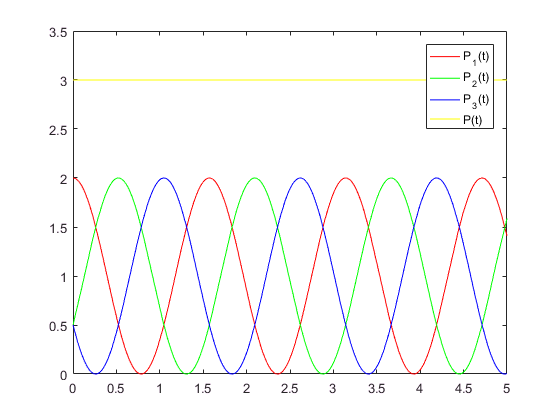

%%
syms x;
f = @(x) x^2;

% fplot(f(x));


%%
syms t u w R;
P1_f = @(t, u, w, R) (u*cos(w*t))^2/R;
% fplot(P1_f(t, 10, 2, 50));

%%
P1 = (u*cos(w*t + 0     ))^2/R;
P2 = (u*cos(w*t + 2*pi/3))^2/R;
P3 = (u*cos(w*t - 2*pi/3))^2/R;
P  = P1 + P2 + P3;
simplify(P)

p1 = subs(P1, [u w R], [10 2 50]);
p2 = subs(P2, [u w R], [10 2 50]);
p3 = subs(P3, [u w R], [10 2 50]);
fplot(p1, 'r');
hold on;
fplot(p2, 'g');
fplot(p3, 'b');
fplot(p1+p2+p3, 'y');
axis([0 5 0 3.5]);
legend('P_1(t)', 'P_2(t)', 'P_3(t)', 'P(t)');
hold off;

Leistung ist / bleibt konstant!

## 4.2 Drehmoment

Das Moment sinkt bei konstanter Leistung mit zunehmender Drehzahl.

## 4.3 Drehfeld

a

%%
syms A_L I N;

phi   = degtorad(30);
phi_U = degtorad(120);

% Analytisch
B_0 = A_L * N * I;
B_A = [0         -1      ]' * cos(w*t + 0);
B_B = [-cos(phi) sin(phi)]' * cos(w*t - phi_U);
B_C = [cos(phi)  sin(phi)]' * cos(w*t + phi_U);


B_G = B_A + B_B + B_C;
B_G

$$B\_G = \left(\begin{array}{c} \frac{\sqrt{3}\,\cos\left(\frac{2\,\pi }{3}+t\,w\right)}{2}-\frac{\sqrt{3}\,\cos\left(\frac{2\,\pi }{3}-t\,w\right)}{2}\\ \frac{\cos\left(\frac{2\,\pi }{3}+t\,w\right)}{2}-\cos\left(t\,w\right)+\frac{\cos\left(\frac{2\,\pi }{3}-t\,w\right)}{2} \end{array}\right)$$

simplify(B_G)

$$ans = \left(\begin{array}{c} -\frac{3\,\sin\left(t\,w\right)}{2}\\ -\frac{3\,\cos\left(t\,w\right)}{2} \end{array}\right)$$

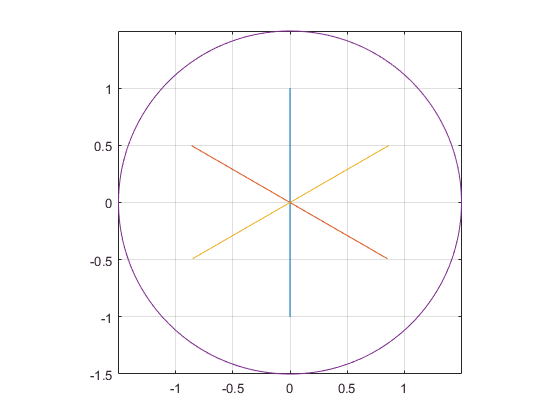


% Plotten
b_a = subs(B_A, w, 2);
b_b = subs(B_B, w, 2);
b_c = subs(B_C, w, 2);
b   = b_a + b_b + b_c;

fplot(b_a(1), b_a(2));
hold on;
grid on;
fplot(b_b(1), b_b(2));
fplot(b_c(1), b_c(2));
fplot(b(1), b(2));
daspect([1 1 1]);

a